# 034IN - FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL - A.Y. 2023-2024

# Full Examination - June 21 2024

# PART 1 - Problem 2

**Tag List**: `[STANDARD ASSESSMENT] [PARTIAL CREDIT] [SYMBOLIC MATH TOOLBOX] [CONTROL TOOLBOX]`

Consider the LTI system described by the block scheme in Figure

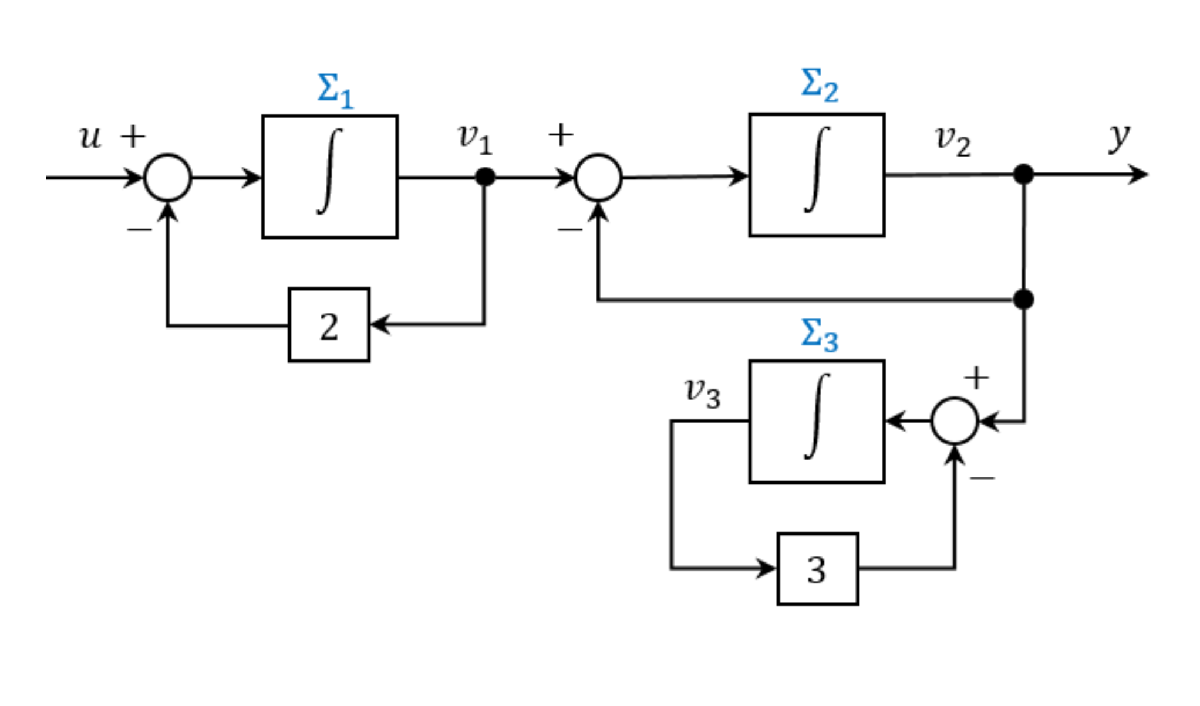

where $\Sigma_1$, $\Sigma_2$ and $\Sigma_3$ are integrators with initial conditions


$$v_1(0) = +2.25\,,\; v_2(0) = 0\,,\;v_3(0) = -4.81$$


The input function is given by  


$$u(t) = 5\,e^{-4t}\cdot \mathbf{1}(t)$$


where $\mathbf{1}(t)$ denotes the unit step function.

## **Assignment**:

- Determine a state-space representation of the LTI system. 

- [**MANDATORY**] **Sort** the state variables in the state representation according to the labelling of the "integrator" systems, i.e. **firstly**, the state variables corresponding to  $\Sigma_1$, **then** the state variables associated with  $\Sigma_2$ and **last,** the state variables corresponding to $\Sigma_3$.

- Assign the matrices $A\,,\;B\,,\;C$and $D$ of the obtained state representation to the **symbolic**** variables** `symA`, `symB`, `symC` and `symD`.

- Properly exploiting the Laplace transform, **determine** **analitically** the **output** **response** $y(t)$, given the assigned initial conditions and the input function $u(t)$.  Store the resulting response in the **symbolic** **variable** `symYt.`

- Assign the matrices $A\,,\;B\,,\;C$and $D$ of the obtained state representation to the **numeric**** variables** `matA`, `matB`, `matC` and `matD`.

- Using the matrices `matA`, `matB`, `matC` and `matD `define an LTI system description in state-space form, called `stateLTIsys`, exploiting the command `ss( )`. **Convert** this representation in a transfer function representation, exploiting the command` tf( ).` Assign the obtained transfer function to the variable `tfLTIsys`.

- Evaluate the eigenvalues of `matA` and store the result in the numeric array `eigA`.

- Evaluate zeros, poles and static gain of `tfLTIsys` and save the results in the **numeric** **variables** **zerosTF**, **polesTF** and **gainTF**.

## Solution

### Analysis of the Scheme - The State-Space Equations of the Dynamic System

Let's consider the initial bullet points:

- **P1**: Determine a state-space representation of the LTI system. 

- **P2:** [**MANDATORY**] **Sort** the state variables in the state representation according to the labelling of the "integrator" systems, i.e. **firstly**, the state variables corresponding to  $\Sigma_1$, **then** the state variables associated with  $\Sigma_2$ and **last,** the state variables corresponding to $\Sigma_3$.

Indeed the scheme depicted in the Figure is not an effective block diagram: it's a simple graphical representation of an Ordinary Differential Equation (ODE) of third order. Let's examine in detail the **first part of the scheme**, corresponding to the integrator with label $\Sigma_1$:

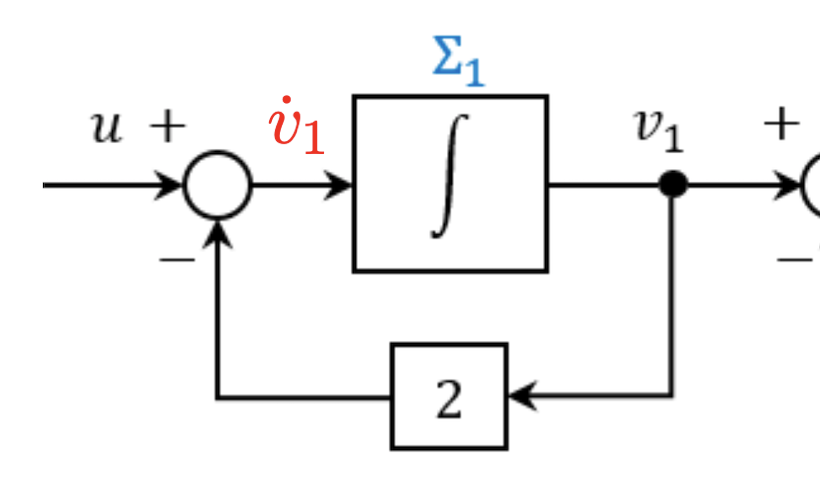

Let's associate the variable $\dot{v}_1$ with the input branch  of the "integrator" $\Sigma_1$, as in the figure above (in red in the picture). Simply by inspection of the scheme, we can write


$$\dot{v}_1 (t) = -2\,v_1(t) + u(t)$$


Moreover, considering the output branch of the integrator $\Sigma_1$, the following relation holds


$$y_1(t) = v_1(t)$$
 

Thus, this portion of the scheme corresponds to the equations


$$\left\{ \begin{array}{rcl}
\dot{v}_1(t) &=& -2\,v_1(t) +u(t) \\
y_1(t) &=& v_1(t)
\end{array} \right.$$


Let's focus on **the central part of the scheme**

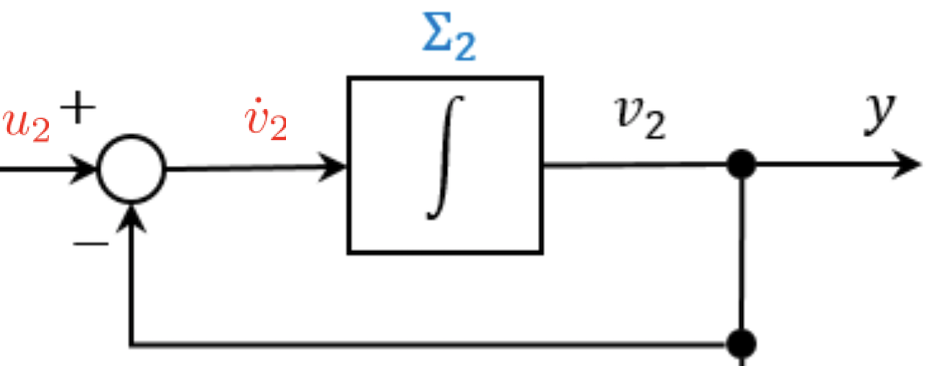

Let's associate the variable $\dot{v}_2$ with the input branch  of the "integrator" $\Sigma_2$, as in the figure above (in red in the picture). Moreover, label as input $u_2$ the branch on the left of the scheme portion, entering in the summation block. Now we are able to write the equations corresponding to this part of the scheme:


$$\left\{ \begin{array}{rcl}
\dot{v}_2(t) &=& -v_2(t)+u_2(t)\\
y(t) &=& v_2(t) 
\end{array} \right.$$


Taking into consideration the connection between this part and the previous $\Sigma_1$ part of the scheme, it holds: $u_2(t) = y_1(t)$.

Regarding the **last portion of the scheme**, 

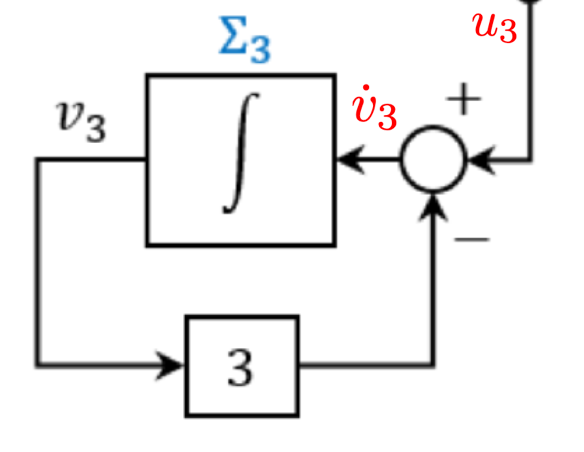

with a similar approach we obtain the equation


$$\dot{v}_3(t) = -3\,v_3(t) + u_3(t)$$


**Note**: this portion of the scheme has no output branch, so there is no output signal. The input $u_3(t)$ is the output signal of the $\Sigma_2$ part of the scheme: $u_3(t) = v_2(t)$

#### Summing Up

 By analysing the scheme, we obtained the following system of differential and algebraic equations:


$$\left\{ \begin{array}{rcl}
\dot{v}_1(t) &=& -2\,v_1(t) +u(t) \\
\dot{v}_2(t) &=& -v_2(t)+u_2(t)\\
\dot{v}_3(t) &=& -3\,v_3(t) + u_3(t)\\
y_1(t) &=& v_1(t)\\
u_2(t) &=& y_1(t) \\
u_3(t) &=& v_2(t) \\
y(t) &=& v_2(t)
\end{array} \right.$$


By labeling as **the** **state** **variables** $x_1,\,x_2,\,x_3$ the outputs $v_1,\,v_2,\,v_3$ of the integrators (as usual, see the examples in Part-2 of the course material, pp. 12-19), and eliminating the auxiliariy variables [i.e. $u_2$, $u_3$, $y_1$, and $y_2$], we obtain the desired **state-space realisation**:


$$\left\{ \begin{array}{rcl}
\dot{x}_1(t) &=& -2\,x_1(t) + u(t) \\
\dot{x}_2(t) &=& x_1(t) -x_2(t) \\
\dot{x}_3(t) &=& x_2(t) -3\,x_3(t) \\
y(t) &=& x_2(t)
\end{array} \right.$$


Finally, the matrices $A,\,B,\,C$ and $D$ are


$$A = \left[ \begin{array}{ccc}
-2 & 0 & 0 \\
+1 & -1 & 0 \\
0 & +1 & -3
\end{array} \right] \quad
B = \left[ \begin{array}{c}
+1 \\ 0 \\ 0
\end{array} \right] \quad 
C = \big[ \begin{array}{ccc}
0 & +1 & 0
\end{array} \big] \quad 
D = \big[ 0 \big]
$$


- **P3**: Assign the matrices $A\,,\;B\,,\;C$and $D$ of the obtained state representation to the **symbolic**** variables** `symA`, `symB`, `symC` and `symD`.

% --- 3rd bullet point
% the matrices A, B, C, and D, according to the state equuations

% the matrix symA
symA = sym([-2,  0 , 0;
        +1, -1 , 0;
         0, +1, -3]);

% the matrix symB
symB = sym([1;0;0]);

% the matrix symC
symC = sym([0, 1, 0]);

% the matrix symD
symD = sym(0);



- **P4**: Properly exploiting the Laplace transform, **determine** **analitically** the **output** **response** $y(t)$, given the assigned initial conditions and the input function $u(t)$.  Store the resulting response in the **symbolic** **variable** `symYt.`

% --- the 4th bullet point
% evaluation of the output movement

syms s t

x0 = sym([2.25; 0; -4.81]); % the initial state 

u = 5*exp(-4*t);  % the input as symbolic expression
Us = laplace(u,s) % the corresponding Laplace transform

$$Us = \frac{5}{s+4}$$


sIA = s*eye(size(symA))-symA; % the symbolic matrix (sI-A)
sIA1 = inv(sIA);              % the inverse matrix of (sI-A)

% let's compute the Laplace transform of the output movement
%
% Note: the movement is the summation of the "zero-input" movement 
% [or "free movement"] (depending ONLY from the state initial 
% condition) and the so-called "zero-state" movement [or 
% "forced movement"] (depending ONL:Y from the input)
%
Ys = simplify(symC*sIA1*x0+symC*sIA1*symB*Us)

$$Ys = \frac{9}{4\,\left(s+1\right)\,\left(s+2\right)}+\frac{5}{\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}$$


% from the Laplace transform to the time-domain variable y(t)
symYt = simplify(ilaplace(Ys,s,t))

$$symYt = \frac{47\,{\mathrm{e}}^{-t}}{12}-\frac{19\,{\mathrm{e}}^{-2\,t}}{4}+\frac{5\,{\mathrm{e}}^{-4\,t}}{6}$$

- **P5**: Assign the matrices $A\,,\;B\,,\;C$and $D$ of the obtained state representation to the **numeric**** variables** `matA`, `matB`, `matC` and `matD`.

- **P6**: Using the matrices `matA`, `matB`, `matC` and `matD `define an LTI system description in state-space form, called `stateLTIsys`, exploiting the command `ss( )`. **Convert** this representation in a transfer function representation, exploiting the command` tf( ).` Assign the obtained transfer function to the variable `tfLTIsys`.

% --- the 5th bullet point
% from symbolic to numerical matrices
matA = double(symA);
matB = double(symB);
matC = double(symC);
matD = double(symD);

% --- the 6th bullet point
% calculate a state-space representation  and a I/O reepresentation 
% of the LTI system in MATLAB

% the state-space description
stateLTIsys = ss(matA, matB, matC, matD)


stateLTIsys =
 
  A = 
       x1  x2  x3
   x1  -2   0   0
   x2   1  -1   0
   x3   0   1  -3
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


% the transfer function of the same LTI system
tfLTIsys = tf(stateLTIsys)


tfLTIsys =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties


- **P7**: Evaluate the eigenvalues of `matA` and store the result in the numeric array `eigA`.

- **P8**: Evaluate zeros, poles and static gain of `tfLTIsys` and save the results in the **numeric** **variables** **zerosTF**, **polesTF** and **gainTF**.

% the 7th bullet point

% as requested, let's evaluate the eigenvalues 
% of the NUMERICAL matrix matA
eigA = eig(matA)

eigA =     -3
    -1
    -2




% the 8th point
% calculation of zeros, poles and static gain 
% of the previously computed transfer function
zerosTF = zero(tfLTIsys)


zerosTF =

  0×1 empty double column vector



polesTF = pole(tfLTIsys)

polesTF =     -2
    -1


gainTF = dcgain(tfLTIsys)

gainTF = 0.5000